# Histogram Equalization - Image preprocessing technique

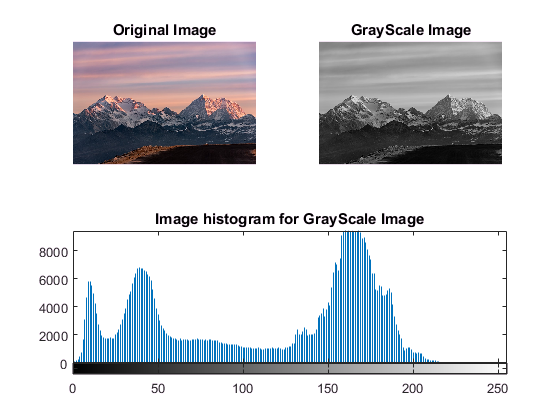

% Read image file
img = imread('img.jpg');
% Convert to graysclae
img_gr = rgb2gray(img);
% display original image
figure;
subplot(2,2,1);
imshow(img);
title('Original Image');
% display grayscale image
subplot(2,2,2);
imshow(img_gr);
title('GrayScale Image');
% display image histogram
subplot(2,2,3:4);
imhist(img_gr);
title('Image histogram for GrayScale Image');

% performing histogram Equalization
img_histeq = histeq(img_gr);

% performing adaptive hsitogram equalization
ad_img_histeq = adapthisteq(img_gr);

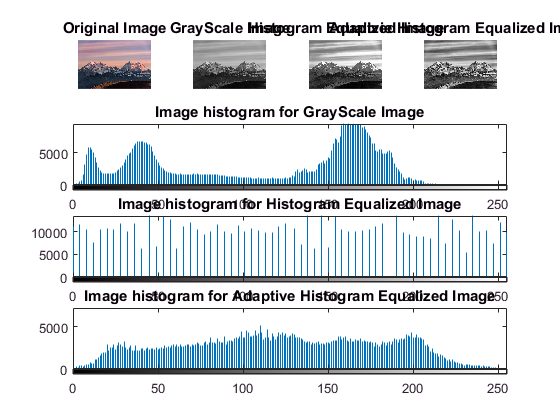

% Comparing Images
% display original image
figure;
subplot(4,4,1);
imshow(img);
title('Original Image');
% display grayscale image
subplot(4,4,2);
imshow(img_gr);
title('GrayScale Image');
% display histogram equalized image
subplot(4,4,3);
imshow(img_histeq);
title('Histogram Equalized Image');
% display adaptive histogram equalized image
subplot(4,4,4);
imshow(ad_img_histeq);
title('Adaptvie Histogram Equalized Image');
% display image histogram
subplot(4,4,5:8);
imhist(img_gr);
title('Image histogram for GrayScale Image');
% display equalized image histogram
subplot(4,4,9:12);
imhist(img_histeq);
title('Image histogram for Histogram Equalized Image');
% display adaptive histogram equalized image
subplot(4,4,13:16);
imhist(ad_img_histeq);
title('Image histogram for Adaptive Histogram Equalized Image');